j_max = 10.0;
a_max = 2.0;
v_max = 1;

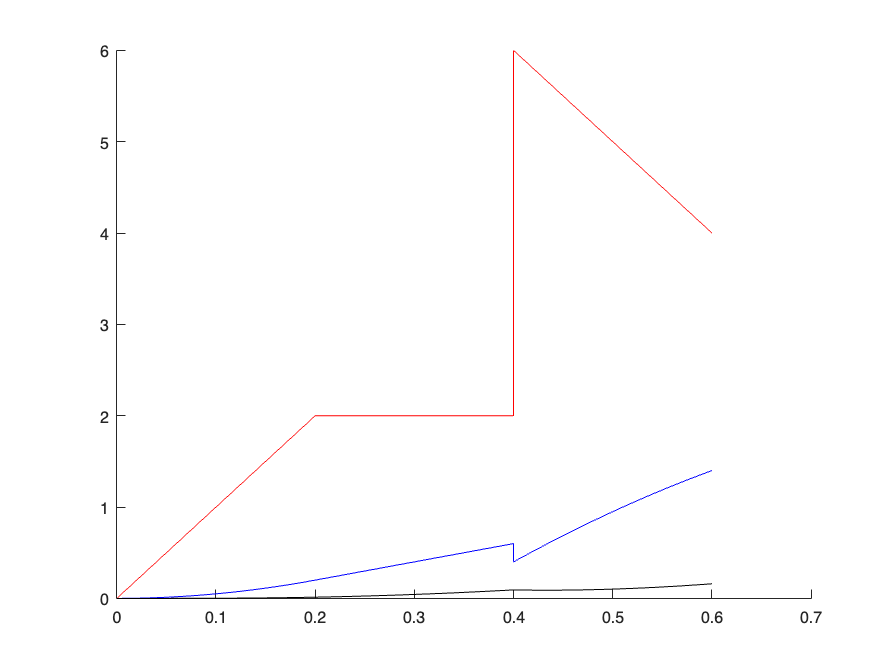

%case 1
t_1 = 0:.01:(a_max/j_max);
t_2 = (a_max/j_max):.01:(2*a_max/j_max);
t_3 = 2*(a_max/j_max):.01:3*(a_max/j_max);
%{
t_2m;
t_3m;
t_4m;
t_5m;
t_6m;
t_7m;
v_max
%}

syms t;
v_1 = j_max*t.^2/2;
a_1 = diff(v_1);
p_1 = int(v_1,[0 t]);

t = t_1;
v_s = subs(v_1,t);
a_s = subs(a_1,t);
p_s = subs(p_1,t);
time = t;


syms t;
v_2 = a_max*t + v_s(end);
a_2 = diff(v_2);
p_2 = int(v_2,[0 t]) + p_s(end);

t = t_2;
v_s = [v_s subs(v_2,(t - time(end)))];
a_s = [a_s subs(a_2,(t - time(end)))];
p_s = [p_s subs(p_2,(t - time(end)))];
time = [time t];

syms t;
v_3 = -j_max*(t - t_3(end))^2/2 + v_max + v_s(end);
a_3 = diff(v_3);
p_3 = int(v_3,[0 t]) + p_s(end);

t = t_3;
v_s = [v_s subs(v_3,(t - time(end)))+v_s(end)];
a_s = [a_s subs(a_3,(t - time(end)))];
p_s = [p_s subs(p_3,(t - time(end)))];
time = [time t];

%{
v_3 = -j_max*(t_3 - t_3m)^2/2 + v_max
v_4 = v_max
v_5 = -j_max*(t_5 - t_4m)^2/2 + v_max
v_6 = -a_max*t_2;
%}

hold on;
plot(time,v_s,'b')
plot(time,a_s,'r')
plot(time,p_s,'k')